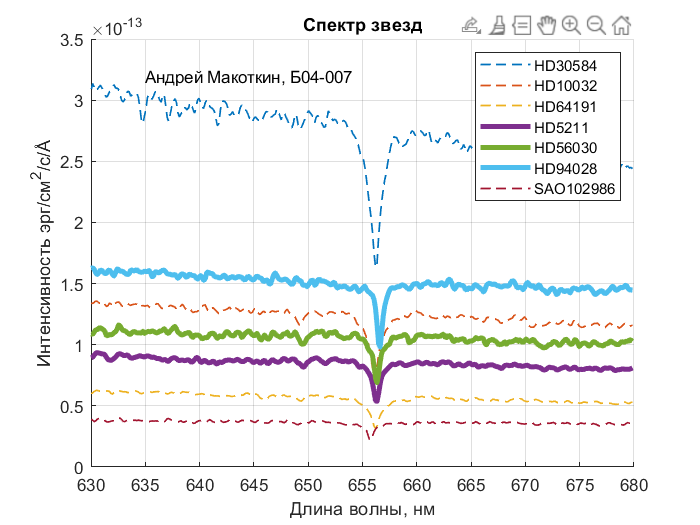

% Импортируйте данные из csv-файлов

% Определите константы
lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

% Определите диапазон длин волн

% Рассчитайте скорости звезд относительно Земли

% Постройте график

% Сохраните график
spectra = importdata('spectra.csv');
starNames = importdata("star_names.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
str = size(spectra, 1);
stl = size(spectra, 2);
inten = zeros([1 stl]);
index = zeros([1 stl]);
speed = zeros([1 stl]);  
lambdaEnd = lambdaStart + (str-1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';
hold on;
for i = 1:stl
    s = spectra(:,i);
    [m,id] = min(s);
    inten(1,i) = m;
    index(1,i) = id;
    lambdaHa = lambda(id);
    z = (lambdaHa / lambdaPr) - 1;
    sp = z*speedOfLight;
    speed(1,i) = sp;
    
    if sp>0
        plot(lambda, s,"LineWidth",3);
    else 
        plot(lambda, s,"--","LineWidth",1);
    end
    set(gcf, 'visible', 'on');
    xlabel('Длина волны, нм');
    ylabel(['Интенсивность эрг/см^2/с/',char(197)]);
    title({'Спектр звезд'});
    grid on;
    
end
legend(starNames);
text(635,3.2*10^-13, ['Андрей Макоткин, Б04-007']);
hold off;

speed = speed';
movaway = starNames(speed>0);





